Este programa halla la solución aproximada por el método de Runge Kutta Orden 4 del sistema de ecuaciones diferenciales de primer orden

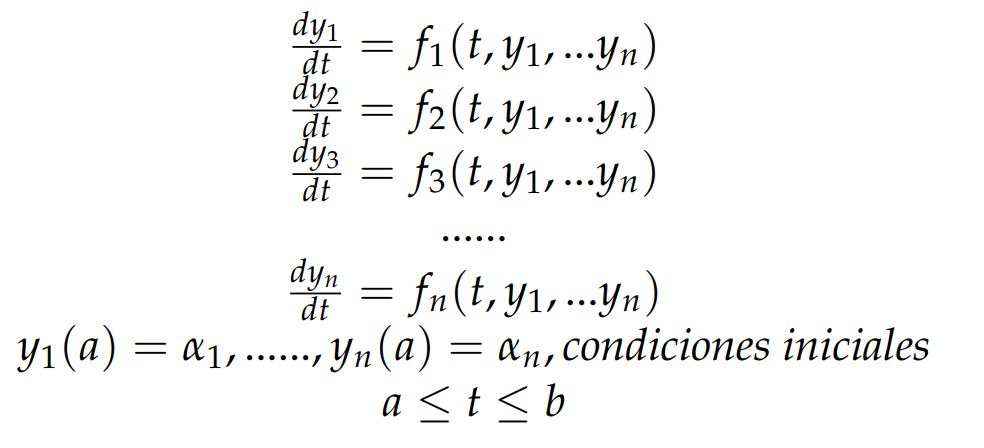

Equivalente al sistema: 

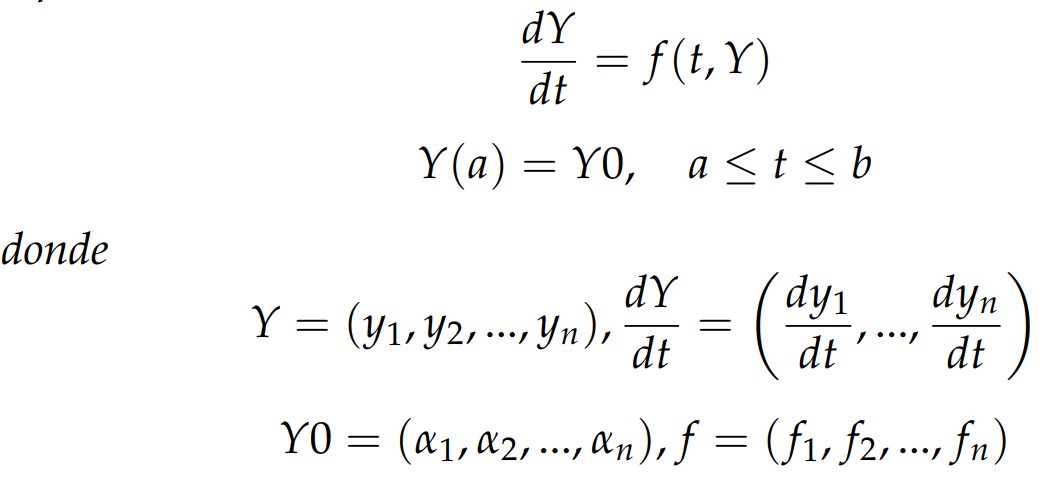

Y0 es el vector renglón de condiciones iniciales

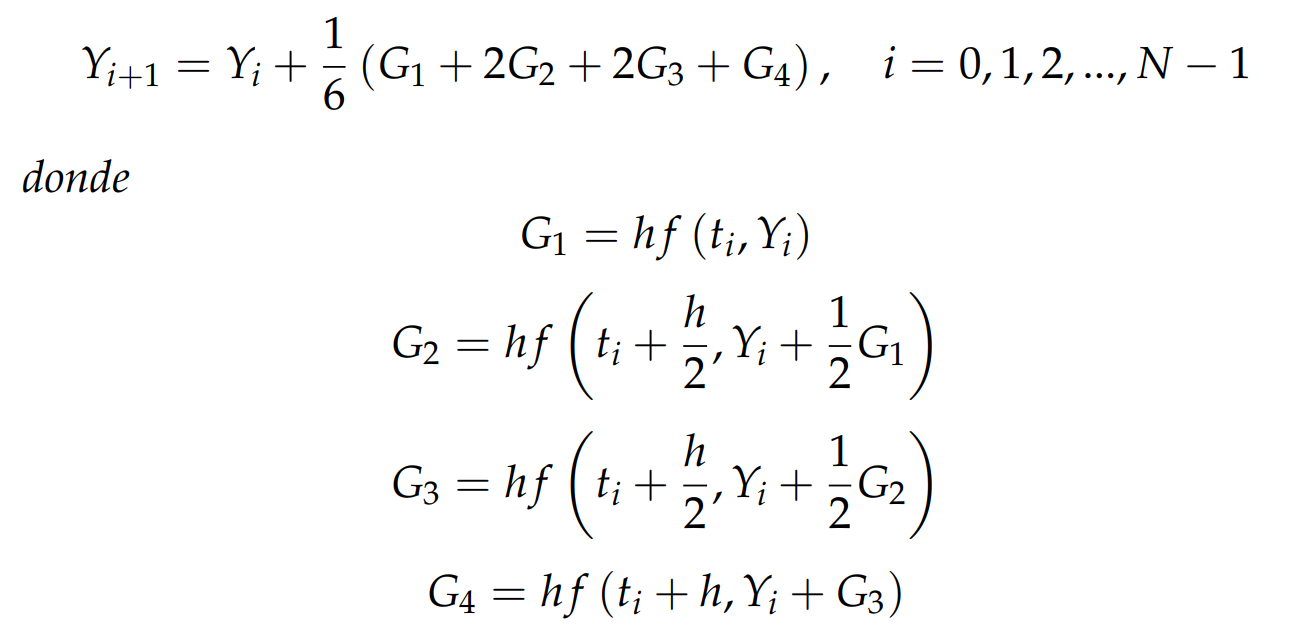

h es el tamaño de paso de la discretización del intervalo [a,b]

function A=RungeKuttaO4(f,Y0,a,b,h)
N=ceil((b-a)/h);
t=linspace(a,b,N+1); % [a,t+h,...]
n=length(Y0);
Y=zeros(N+1,n);
Y(1,:)=Y0;
for i=1:N
    G1=h*f(t(i),Y(i,:));
    G2=h*f(t(i)+h/2,Y(i,:)+G1/2);
    G3=h*f(t(i)+h/2,Y(i,:)+G2/2);
    G4=h*f(t(i)+h,Y(i,:)+G3);
    Y(i+1,:)=Y(i,:)+(G1+2*G2+2*G3+G4)/6;
end
A=[t' Y];
[~,col]=size(Y);

if col==1
plot(A(:,1),A(:,2))
grid minor
xlabel('t')
ylabel('Y')
legend('y1','Location','best')
A=array2table(A,'VariableNames',{'t','y1'})
elseif col==2
plot(A(:,1),A(:,2),A(:,1),A(:,3)) 
grid minor
xlabel('t')
ylabel('Y')
legend('y1','y2','Location','best')
A=array2table(A,'VariableNames',{'t','y1','y2'})
elseif col==3
plot(A(:,1),A(:,2),A(:,1),A(:,3),A(:,1),A(:,4)) 
grid minor
xlabel('t')
ylabel('y1')
legend('y1','y2','y3','Location','best')
A=array2table(A,'VariableNames',{'t','y1','y2','y3'})
end


